%%%%%%%%%%%%%%%%%%%%%%
%%%import data
%%%%%%%%%%%%%%%%%%%%%%

%% find current working folder
fp = fileparts(matlab.desktop.editor.getActiveFilename);
cd(fp) %% change to code folder
cd ../../Data/Processed/EtO/'Data Conversions' %change to data folder

%%canister data, including data with all flags
%SDK
ARSDK = readtimetable("AR SDK.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ARSDKnoLK = readtimetable("AR SDK.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ARSDKnoHg = readtimetable("AR SDK.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");
ARSDKATEC = readtimetable("AR SDK.xlsx", "Sheet", "ATEC", "VariableNamingRule", "preserve");
ARSDKATECnoLK = readtimetable("AR SDK.xlsx", "Sheet", "ATEC no LK", "VariableNamingRule", "preserve");
ARSDKATECnoHg = readtimetable("AR SDK.xlsx", "Sheet", "ATEC no 0 Hg", "VariableNamingRule", "preserve");
ARSDKEnt = readtimetable("AR SDK.xlsx", "Sheet", "Ent", "VariableNamingRule", "preserve");
ARSDKEntnoLK = readtimetable("AR SDK.xlsx", "Sheet", "Ent no LK", "VariableNamingRule", "preserve");
ARSDKEntnoHg = readtimetable("AR SDK.xlsx", "Sheet", "Ent no 0 Hg", "VariableNamingRule", "preserve");

%STER
ARSTER = readtimetable("AR STER.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ARSTERnoLK = readtimetable("AR STER.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ARSTERnoHg = readtimetable("AR STER.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%SSG
ARSSG = readtimetable("AR SSG.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ARSSGnoLK = readtimetable("AR SSG.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ARSSGnoHg = readtimetable("AR SSG.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%COV
ARCOV = readtimetable("AR COV.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ARCOVnoLK = readtimetable("AR COV.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ARCOVnoHg = readtimetable("AR COV.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%%receptors
cd ..
points = readtable("mapPoints.xlsx", "sheet", "From Matlab"); %grab receptor data
pointsWHcenter = readtable("mapPoints.xlsx", "sheet", ...
    "From Matlab, warehouse center"); %grab receptor with COV warehouse as center

%%met data, but only met data needed
cd ../Met
rawMetSDK = readtimetable("Met_SDK.xlsx"); %SDK data 8/19-8/22
rawMetSTER = readtimetable("WRF wind data.xlsx", "Sheet", "STER"); %STER 5/19-7/22
rawMetSSG = readtimetable("WRF wind data.xlsx", "Sheet", "SSG"); %SSG 5/19-7/22
rawMetCOV = readtimetable("WRF wind data.xlsx", "Sheet", "COV"); %COV 5/19-7/22

cd ../..

%%%%%%%%%%%%%%%%%%%%%%
%%% separation of upwind/downwind AR
%%%%%%%%%%%%%%%%%%%%%%

%%INPUTS
dataSDK = ARSDKEnt(:, ["Ent_ERG", "Ent_ERG_2"]); %passive SDK at ERG ONLY
dataSTER = ARSTER; %STER
dataSSG = ARSSG; %SSG
dataCOV = ARCOV; %COV
tol = 50; %minimum tolerance for binning
degUpwind = 90; %upwind degree tolerance
degDownwind = 90; %downwind degree tolerance
WDRSDK = rawMetSDK(:, "WDR"); %wind SDK
WDRSTER = rawMetSTER(:, "WDR"); %wind STER
WDRSSG = rawMetSSG(:, "WDR"); %wind SSG
WDRCOV = rawMetCOV(:, "WDR"); %wind COV

%%%different options for calculation
%%%split up by met analysis
%%pre-format for separation function
%%STER
temp = table2array(points(3:9, [5, 6])); %S1, S2, S3, S4, S5, S6, S7
%match column structure of STER eto table
receptorsSTER = [temp(1, :)', temp(1, :)', temp(2, :)', temp(2, :)', ...
    temp(3, :)', temp(3, :)', temp(4, :)', temp(4, :)', ...
    temp(5, :)', temp(6, :)', temp(7, :)'];
receptorsSTER = array2table(receptorsSTER); %turn into table
%rename to match etoSSG
varNames = ARSTER.Properties.VariableNames;
receptorsSTER = renamevars(receptorsSTER, receptorsSTER.Properties.VariableNames, ...
    varNames);
degFromNSTER = table2array(receptorsSTER(2, :));

%%SSG
temp = table2array(points(12:15, [5, 6])); %F1, F2, F3, F4
%match column structure of SSG eto table
receptorsSSG = [temp(1, :)', temp(1, :)', temp(2, :)', temp(2, :)', ...
    temp(3, :)', temp(4, :)', temp(4, :)'];
receptorsSSG = array2table(receptorsSSG); %turn into table
%rename to match etoSSG
varNames = ARSSG.Properties.VariableNames;
receptorsSSG = renamevars(receptorsSSG, receptorsSSG.Properties.VariableNames, ...
    varNames);
degFromNSSG = table2array(receptorsSSG(2, :));

%%COV; KEY MODIFICATION: C1 ALWAYS DOWNWIND bc at fenceline
temp = table2array(points(20:26, [5, 6])); %C2, C3, C4, C5, C7, C8, C9
%match column structure of COV eto table
receptorsCOV = [temp(1, :)', temp(1, :)', temp(2, :)', temp(2, :)', ...
    temp(3, :)', temp(3, :)', temp(4, :)', temp(4, :)', temp(5, :)', ...
    temp(6, :)', temp(7, :)'];
receptorsCOV = array2table(receptorsCOV); %turn into table
%rename to match etoCOV (except for C1)
varNames = ARCOV.Properties.VariableNames(2:end);
receptorsCOV = renamevars(receptorsCOV, receptorsCOV.Properties.VariableNames, ...
    varNames);
degFromNCOV = table2array(receptorsCOV(2, :));

%%separation function
[upwindSTER, downwindSTER, unbinnedSTER, percUpwindWDRSTER, percDownwindWDRSTER, statsSTER] = ...
    upwindDownwind(degFromNSTER, degUpwind, degDownwind, WDRSTER, tol, dataSTER); %STER
[upwindSSG, downwindSSG, unbinnedSSG, percUpwindWDRSSG, percDownwindWDRSSG, statsSSG] = ...
    upwindDownwind(degFromNSSG, degUpwind, degDownwind, WDRSSG, tol, dataSSG); %SSG
[upwindCOV, downwindCOV, unbinnedCOV, percUpwindWDRCOV, percDownwindWDRCOV, statsCOV] = ...
    upwindDownwind(degFromNCOV, degUpwind, degDownwind, WDRCOV, tol, dataCOV(:, 2:end)); %COV, excluding C1
%% stitching back C1 with rest of COV dataset
downwindC1 = dataCOV(:, 1); % C1; all data is downwind
otherC1 = downwindC1;
otherC1.C1(:) = nan; % rest of C1 (upwind and unbinned) is nan
% stitch C1 to front of timetables
upwindCOV = [otherC1, upwindCOV];
downwindCOV = [downwindC1, downwindCOV];
unbinnedCOV = [otherC1, unbinnedCOV];

%%grab inds or days with coupled observations
%all data
outTTSTER = avSameTime(dataSDK, dataSTER); %[SDKavg, SDKstd, STERavg, STERstd]
outTTSSG = avSameTime(dataSDK, dataSSG); %[SDKavg, SDKstd, SSGavg, SSGstd]
outTTCOV = avSameTime(dataSDK, dataCOV); %[SDKavg, SDKstd, COVavg, COVstd]

%upwind
outUpwindTTSTER = avSameTime(dataSDK, upwindSTER); %[SDKavg, SDKstd, STERavg, STERstd]
outUpwindTTSSG = avSameTime(dataSDK, upwindSSG); %[SDKavg, SDKstd, SSGavg, SSGstd]
outUpwindTTCOV = avSameTime(dataSDK, upwindCOV); %[SDKavg, SDKstd, COVavg, COVstd]

%downwind
outDownwindTTSTER = avSameTime(dataSDK, downwindSTER); %[SDKavg, SDKstd, STERavg, STERstd]
outDownwindTTSSG = avSameTime(dataSDK, downwindSSG); %[SDKavg, SDKstd, SSGavg, SSGstd]
outDownwindTTCOV = avSameTime(dataSDK, downwindCOV); %[SDKavg, SDKstd, COVavg, COVstd]

%%subtraction of each individual near-source site by SDK, separated also by upwind, downwind, and all
%STER
inds = ismember(dataSTER.time, outTTSTER.time); %times SDK and STER match
temp = timetable2array(dataSTER(inds, :)); %grab all STER data
temp = temp - repmat(outTTSTER.avg1, 1, size(temp, 2));
diffSTER = array2timetable(temp, "RowTimes", outTTSTER.time, ...
    "VariableNames", dataSTER.Properties.VariableNames); %STER, all data

inds = ismember(upwindSTER.time, outUpwindTTSTER.time); %times SDK and upwind STER match
temp = timetable2array(upwindSTER(inds, :)); %grab all upwind STER data
temp = temp - repmat(outUpwindTTSTER.avg1, 1, size(temp, 2));
diffUpwindSTER = array2timetable(temp, "RowTimes", outUpwindTTSTER.time, ...
    "VariableNames", dataSTER.Properties.VariableNames); %STER, upwind

inds = ismember(downwindSTER.time, outDownwindTTSTER.time); %times SDK and downwind STER match
temp = timetable2array(downwindSTER(inds, :)); %grab all downwind STER data
temp = temp - repmat(outDownwindTTSTER.avg1, 1, size(temp, 2));
diffDownwindSTER = array2timetable(temp, "RowTimes", outDownwindTTSTER.time, ...
    "VariableNames", dataSTER.Properties.VariableNames); %STER, downwind


%SSG
inds = ismember(dataSSG.time, outTTSSG.time); %times SDK and SSG match
temp = timetable2array(dataSSG(inds, :)); %grab all SSG data
temp = temp - repmat(outTTSSG.avg1, 1, size(temp, 2));
diffSSG = array2timetable(temp, "RowTimes", outTTSSG.time, ...
    "VariableNames", dataSSG.Properties.VariableNames); %SSG

inds = ismember(upwindSSG.time, outUpwindTTSSG.time); %times SDK and upwind SSG match
temp = timetable2array(upwindSSG(inds, :)); %grab all upwind SSG data
temp = temp - repmat(outUpwindTTSSG.avg1, 1, size(temp, 2));
diffUpwindSSG = array2timetable(temp, "RowTimes", outUpwindTTSSG.time, ...
    "VariableNames", dataSSG.Properties.VariableNames); %SSG, upwind

inds = ismember(downwindSSG.time, outDownwindTTSSG.time); %times SDK and downwind SSG match
temp = timetable2array(downwindSSG(inds, :)); %grab all downwind SSG data
temp = temp - repmat(outDownwindTTSSG.avg1, 1, size(temp, 2));
diffDownwindSSG = array2timetable(temp, "RowTimes", outDownwindTTSSG.time, ...
    "VariableNames", dataSSG.Properties.VariableNames); %SSG, downwind


%COV
inds = ismember(dataCOV.time, outTTCOV.time); %times SDK and COV match
temp = timetable2array(dataCOV(inds, :)); %grab all COV data
temp = temp - repmat(outTTCOV.avg1, 1, size(temp, 2));
diffCOV = array2timetable(temp, "RowTimes", outTTCOV.time, ...
    "VariableNames", dataCOV.Properties.VariableNames); %COV

inds = ismember(upwindCOV.time, outUpwindTTCOV.time); %times SDK and upwind COV match
temp = timetable2array(upwindCOV(inds, :)); %grab all upwind COV data
temp = temp - repmat(outUpwindTTCOV.avg1, 1, size(temp, 2));
diffUpwindCOV = array2timetable(temp, "RowTimes", outUpwindTTCOV.time, ...
    "VariableNames", dataCOV.Properties.VariableNames); %COV, upwind

inds = ismember(downwindCOV.time, outDownwindTTCOV.time); %times SDK and downwind COV match
temp = timetable2array(downwindCOV(inds, :)); %grab all downwind COV data
temp = temp - repmat(outDownwindTTCOV.avg1, 1, size(temp, 2));
diffDownwindCOV = array2timetable(temp, "RowTimes", outDownwindTTCOV.time, ...
    "VariableNames", dataCOV.Properties.VariableNames); %COV, downwind


%%OUTPUTS
upwindSTER; downwindSTER; unbinnedSTER; %separated data for STER
upwindSSG; downwindSSG; unbinnedSSG; %separated data for SSG
upwindCOV; downwindCOV; unbinnedCOV; %separated data for COV
diffSTER; diffUpwindSTER; diffDownwindSTER; %difference data for STER
diffSSG; diffUpwindSSG; diffDownwindSSG; %difference data for SSG
diffCOV; diffUpwindCOV; diffDownwindCOV; %difference data for COV
outTTSTER; outUpwindTTSTER; outDownwindTTSTER; %averaged data for pairwise observations
outTTSSG; outUpwindTTSSG; outDownwindTTSSG; %averaged data for pairwise observations
outTTCOV; outUpwindTTCOV; outDownwindTTCOV; %averaged data for pairwise observations

%%%%%%%%%%%%%%%%%%%%%%
%%% plot to see if data are super different during COV shutdowns
%%%%%%%%%%%%%%%%%%%%%%
shutdownCOV = datetime([2019, 2019, 2020, 2020], ...
    [10, 11, 2, 3], ...
    [30, 8, 22, 2]); %shutdowns between Oct 30 and Nov 8, 2019 and Feb 22 and Mar 2, 2020
indsShutdown = isbetween(diffCOV.Properties.RowTimes, shutdownCOV(1), shutdownCOV(2)); %first period
indsShutdown = indsShutdown | ...
    isbetween(diffCOV.Properties.RowTimes, shutdownCOV(3), shutdownCOV(4)); %second period
controlsCOV = datetime(2020, 3, 31);

%%2. histograms, COV
fi1g = figure('Position', get(0, 'Screensize')); %for saving the figure
hold on
grid on
box on
ax = gca;

% binWidths = 0.0025;
binWidths = 0.0015;
beforeColor = [1, 0, 0];
afterColor = [0, 0.5, 1];

%%all data as histograms
indsBefore = diffCOV.Properties.RowTimes < controlsCOV; %before controls
h1 = histogram(unravelTT(diffCOV(indsBefore & ~indsShutdown, :)), "Normalization", "probability");
h1.BinWidth = binWidths;
h1.EdgeColor = "none"; %remove outer outline
h1.FaceAlpha = 0.5;
h1.FaceColor = beforeColor;
median(unravelTT(diffCOV(indsBefore & ~indsShutdown, :)))

ans = 6.1250e-04


indsAfter = diffCOV.Properties.RowTimes >= controlsCOV; %after controls
h2 = histogram(unravelTT(diffCOV(indsAfter, :)), "Normalization", "probability");
h2.BinWidth = binWidths;
h2.EdgeColor = "none"; %remove outer outline
h2.FaceAlpha = 0.5;
h2.FaceColor = afterColor;
median(unravelTT(diffCOV(indsAfter, :)))

ans = 0


% shutdown
h3 = histogram(unravelTT(diffCOV(indsShutdown, :)), "Normalization", "probability");
h3.BinWidth = binWidths;
h3.EdgeColor = "none"; %remove outer outline
h3.FaceAlpha = 0.5;
h3.FaceColor = [0.6, 0.6, 0.6];
median(unravelTT(diffCOV(indsShutdown, :)))

ans = 1.0000e-03

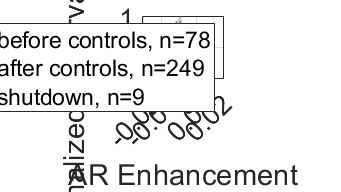


%%line at SDK uncertainties to signify comparison 
xline(0.00126, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)
xline(-0.00126, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)

%%lims
xlim([-0.0209, 0.0259])
xticks(-0.020:0.01:0.020)
ylim([0, 1.01])
% yticks(0:15:60)

%%labels
pbaspect([1.3, 1, 1])
ax.FontSize = 20;
xlabel("AR Enhancement")
ylabel("Normalized Observation Counts")

legend(strcat("before controls, n=", num2str(length(unravelTT(diffCOV(indsBefore & ~indsShutdown, :))))), ...
    strcat("after controls, n=", num2str(length(unravelTT(diffCOV(indsAfter, :))))), ...
    strcat("shutdown, n=", num2str(length(unravelTT(diffCOV(indsShutdown, :))))), ...
    "location", "northeast", "Fontsize", 17)
% legend boxoff

hold off

% %%export the figure
% cd ../Figures
% a = annotation('rectangle',[0 0 1 1],'Color','w'); %add padding
% fn = "Sup COV shutdown.png";
% exportgraphics(fi1g, fn)
% delete(a) %make plot interactive again

% cd ../Data

%%%%%%%%%%%%%%%%%%%%%%
%%% FIGURE 5
%%%%%%%%%%%%%%%%%%%%%%

colorUpwind = [73, 191, 162]/255;
colorDownwind = [226, 84, 175]/255;
controlsSTER = datetime(2020, 4, 8);
controlsSSG = datetime(2021, 1, 26);
controlsCOV = datetime(2020, 3, 31);
patchColor = [0.7, 0.7, 0.7];

%%% STER
fig1 = figure('Position', get(0, 'Screensize')); %for saving the figure
tiledlayout(1, 3)

%%1. time series, STER
xlims = datetime([2019, 2022], [7, 1], 1);
xtickss = xlims(1):calmonths(6):xlims(2);
ax = nexttile([1, 2]);
hold on
grid on
box on

%upwind STER
diffDataUpwindMonthSTER = binByMonth(diffUpwindSTER); %upwind STER, bin by month
times = datenum(diffDataUpwindMonthSTER.Properties.RowTimes); %grab date nums
[hl1, hp] = boundedline(times, diffDataUpwindMonthSTER.avgs, diffDataUpwindMonthSTER.stds, ...
    'o-', 'nan', 'gap', 'alpha', 'transparency', 0.17, 'color', colorUpwind);
hl1.MarkerSize = 8; %change line aspects
hl1.MarkerFaceColor = colorUpwind;
hl1.LineWidth = 3;

%downwind STER
%remove outlier in Sept 2021 (~0.103)
arr = timetable2array(diffDownwindSTER);
ind = timetable2array(diffDownwindSTER) > 0.1;
arr(ind) = nan;
temp = diffDownwindSTER;
temp(:, :) = array2timetable(arr, "RowTimes", temp.Properties.RowTimes);
% temp = diffDownwindSTER; %normal run
diffDataDownwindMonthSTER = binByMonth(temp); %downwind STER, bin by month
times = datenum(diffDataDownwindMonthSTER.Properties.RowTimes); %grab date nums
[hl2, hp] = boundedline(times, diffDataDownwindMonthSTER.avgs, diffDataDownwindMonthSTER.stds, ...
    '^-', 'nan', 'gap', 'alpha', 'transparency', 0.17, 'color', colorDownwind);
hl2.MarkerSize = 8; %change line aspects
hl2.MarkerFaceColor = colorDownwind;
hl2.LineWidth = 3;

% patch for shutdown
x = datenum(datetime([2019, 2020, 2020, 2019],...
    [1, 4, 4, 1], [1, 8, 8, 1])); %end on startup day
y = [-1, -1, 1, 1];
p = patch(x, y, 'red');
p.FaceColor = patchColor; % gray
p.EdgeColor = 'none';
p.FaceAlpha = 0.2; % mostly transparent

%controls lines
xline(datenum(controlsSTER), '--', "linewidth", 2, ...
    "color", "k") %STER
yline(0, '-', "color", [0.5, 0.5, 0.5], "linewidth", 1.3) %comparison against 0 enhancement

%move lines to top
uistack(hl1, 'top')
uistack(hl2, 'top')

%%lims and ticks
xlim(datenum(xlims))
xticks(datenum(xtickss))
ax.XTickLabel = datestr(xtickss, "mmm yyyy");
ylim([-0.0104, 0.0104])
yticks(-0.01:0.005:0.01)
ax.YTickLabel = ["-0.010", "-0.005", "0", "0.005", "0.010"];

%%labels
pbaspect([3, 1, 1])
ax.FontSize = 20;
xlabel("Local Time (EST)")
ylabel("AR Enhancement")
legend("", "", "", "", "", ...
    strcat("upwind, n=", num2str(length(unravelTT(diffUpwindSTER)))), ...
    strcat("downwind, n=", num2str(length(unravelTT(diffDownwindSTER)))))

hold off


%%2. histograms STER
ax = nexttile;
hold on
grid on
box on

binWidths = 0.001;
beforeColor = [1, 0, 0];
afterColor = [0, 0.5, 1];

%%all data as histograms
indsBefore = diffSTER.Properties.RowTimes < controlsSTER; %before controls
h1 = histogram(unravelTT(diffSTER(indsBefore, :)), "Normalization", "probability");
h1.BinWidth = binWidths;
h1.EdgeColor = "none"; %remove outer outline
h1.FaceAlpha = 0.5;
h1.FaceColor = beforeColor;
median(unravelTT(diffSTER(indsBefore, :)))

ans = 5.0000e-05


indsAfter = diffSTER.Properties.RowTimes >= controlsSTER; %after controls
h2 = histogram(unravelTT(diffSTER(indsAfter, :)), "Normalization", "probability");
h2.BinWidth = binWidths;
h2.EdgeColor = "none"; %remove outer outline
h2.FaceAlpha = 0.5;
h2.FaceColor = afterColor;
median(unravelTT(diffSTER(indsAfter, :)))

ans = -1.0000e-04

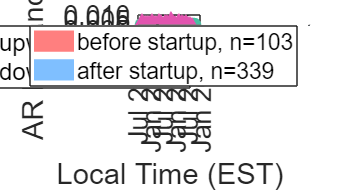


%%line at SDK uncertainties to signify comparison 
xline(0.00126, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)
xline(-0.00126, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)

%%lims
xlim([-0.0208, 0.0208])
xticks(-0.020:0.01:0.020)
ylim([0, 0.6])
% yticks(0:20:80)

%%labels
pbaspect([1.3, 1, 1])
ax.FontSize = 20;
xlabel("AR Enhancement")
ylabel("Normalized Observation Counts")

legend(strcat("before startup, n=", num2str(length(unravelTT(diffSTER(indsBefore, :))))), ...
    strcat("after startup, n=", num2str(length(unravelTT(diffSTER(indsAfter, :))))), ...
    "location", "northeast", "Fontsize", 17)

hold off

%%% SSG
fig2 = figure('Position', get(0, 'Screensize')); %for saving the figure
tiledlayout(1, 3)

%%1. time series, SSG
xlims = datetime([2019, 2022], [7, 1], 1);
xtickss = xlims(1):calmonths(6):xlims(2);
ax = nexttile([1, 2]);
hold on
grid on
box on

%upwind SSG
diffDataUpwindMonthSSG = binByMonth(diffUpwindSSG); %upwind SSG, bin by month
times = datenum(diffDataUpwindMonthSSG.Properties.RowTimes); %grab date nums
[hl3, hp] = boundedline(times, diffDataUpwindMonthSSG.avgs, diffDataUpwindMonthSSG.stds, ...
    'o-', 'nan', 'gap', 'alpha', 'transparency', 0.17, 'color', colorUpwind);
hl3.MarkerSize = 8; %change line aspects
hl3.MarkerFaceColor = colorUpwind;
hl3.LineWidth = 3;

%downwind SSG
diffDataDownwindMonthSSG = binByMonth(diffDownwindSSG); %downwind SSG, bin by month
times = datenum(diffDataDownwindMonthSSG.Properties.RowTimes); %grab date nums
[hl4, hp] = boundedline(times, diffDataDownwindMonthSSG.avgs, diffDataDownwindMonthSSG.stds, ...
    '^-', 'nan', 'gap', 'alpha', 'transparency', 0.17, 'color', colorDownwind);
hl4.MarkerSize = 8; %change line aspects
hl4.MarkerFaceColor = colorDownwind;
hl4.LineWidth = 3;

%controls lines
xline(datenum(controlsSSG), '--', "linewidth", 2, ...
    "color", "k") %SSG
yline(0, '-', "color", [0.5, 0.5, 0.5], "linewidth", 1.3) %comparison against 0 enhancement

%move lines to top
uistack(hl3, 'top')
uistack(hl4, 'top')

%%lims and ticks
xlim(datenum(xlims))
xticks(datenum(xtickss))
ax.XTickLabel = datestr(xtickss, "mmm yyyy");
ylim([-0.0054, 0.0154])
yticks(-0.005:0.005:0.015)
ax.YTickLabel = ["-0.005", "0", "0.005", "0.010", "0.015"];

%%labels
pbaspect([3, 1, 1])
ax.FontSize = 20;
xlabel("Local Time (EST)")
ylabel("AR Enhancement")
legend("", "", "", "", ...
    strcat("upwind, n=", num2str(length(unravelTT(diffUpwindSSG)))), ...
    strcat("downwind, n=", num2str(length(unravelTT(diffDownwindSSG)))))

hold off



%%2. histograms, SSG
ax = nexttile;
hold on
grid on
box on

% binWidths = 0.0025;
binWidths = 0.0015;

%%all data as histograms
indsBefore = diffSSG.Properties.RowTimes < controlsSSG; %before controls
h1 = histogram(unravelTT(diffSSG(indsBefore, :)), "Normalization", "probability");
h1.BinWidth = binWidths;
h1.EdgeColor = "none"; %remove outer outline
h1.FaceAlpha = 0.5;
h1.FaceColor = beforeColor;
medSSGBefore = median(unravelTT(diffSSG(indsBefore, :)))

medSSGBefore = 0.0013


indsAfter = diffSSG.Properties.RowTimes >= controlsSSG; %after controls
h2 = histogram(unravelTT(diffSSG(indsAfter, :)), "Normalization", "probability");
h2.BinWidth = binWidths;
h2.EdgeColor = "none"; %remove outer outline
h2.FaceAlpha = 0.5;
h2.FaceColor = afterColor;
median(unravelTT(diffSSG(indsAfter, :)))

ans = 2.5000e-04

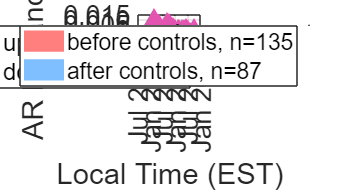


%%line at SDK uncertainties to signify comparison 
xline(0.00126, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)
xline(-0.00126, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)

%%lims
xlim([-0.021, 0.031])
xticks(-0.02:0.01:0.03)
ylim([0, 0.8])
% yticks(0:15:60)

%%labels
pbaspect([1.3, 1, 1])
ax.FontSize = 20;
xlabel("AR Enhancement")
ylabel("Normalized Observation Counts")

legend(strcat("before controls, n=", num2str(length(unravelTT(diffSSG(indsBefore, :))))), ...
    strcat("after controls, n=", num2str(length(unravelTT(diffSSG(indsAfter, :))))), ...
    "location", "northeast", "Fontsize", 17)
% legend boxoff

hold off

%%% COV
fig3 = figure('Position', get(0, 'Screensize')); %for saving the figure
tiledlayout(1, 3)

%%1. time series, COV
xlims = datetime([2019, 2022], [7, 1], 1);
xtickss = xlims(1):calmonths(6):xlims(2);
ax = nexttile([1, 2]);
hold on
grid on
box on

%upwind COV
diffDataUpwindMonthCOV = binByMonth(diffUpwindCOV); %upwind COV, bin by month
times = datenum(diffDataUpwindMonthCOV.Properties.RowTimes); %grab date nums
[hl3, hp] = boundedline(times, diffDataUpwindMonthCOV.avgs, diffDataUpwindMonthCOV.stds, ...
    'o-', 'nan', 'gap', 'alpha', 'transparency', 0.17, 'color', colorUpwind);
hl3.MarkerSize = 8; %change line aspects
hl3.MarkerFaceColor = colorUpwind;
hl3.LineWidth = 3;

%downwind COV
diffDataDownwindMonthCOV = binByMonth(diffDownwindCOV); %downwind COV, bin by month
times = datenum(diffDataDownwindMonthCOV.Properties.RowTimes); %grab date nums
[hl4, hp] = boundedline(times, diffDataDownwindMonthCOV.avgs, diffDataDownwindMonthCOV.stds, ...
    '^-', 'nan', 'gap', 'alpha', 'transparency', 0.17, 'color', colorDownwind);
hl4.MarkerSize = 8; %change line aspects
hl4.MarkerFaceColor = colorDownwind;
hl4.LineWidth = 3;

%controls lines
xline(datenum(controlsCOV), '--', "linewidth", 2, ...
    "color", "k") %COV
yline(0, '-', "color", [0.5, 0.5, 0.5], "linewidth", 1.3) %comparison against 0 enhancement

% patch for shutdown
% first period
x = datenum(datetime(2019,...
    [10, 11, 11, 10], [30, 8, 8, 30])); %shutdown timeline
y = [-1, -1, 1, 1];
p = patch(x, y, 'red');
p.FaceColor = patchColor; % gray
p.EdgeColor = 'none';
p.FaceAlpha = 0.2; % mostly transparent
% second period
x = datenum(datetime(2020,...
    [2, 3, 3, 2], [22, 2, 2, 22])); %shutdown timeline
y = [-1, -1, 1, 1];
p = patch(x, y, 'red');
p.FaceColor = patchColor; % gray
p.EdgeColor = 'none';
p.FaceAlpha = 0.2; % mostly transparent

%move lines to top
uistack(hl3, 'top')
uistack(hl4, 'top')

%%lims and ticks
xlim(datenum(xlims))
xticks(datenum(xtickss))
ax.XTickLabel = datestr(xtickss, "mmm yyyy");
ylim([-0.0104, 0.0104])
yticks(-0.01:0.005:0.01)
ax.YTickLabel = ["-0.010", "-0.005", "0", "0.005", "0.010"];

%%labels
pbaspect([3, 1, 1])
ax.FontSize = 20;
xlabel("Local Time (EST)")
ylabel("AR Enhancement")
legend("", "", "", "", "", "", ...
    strcat("upwind, n=", num2str(length(unravelTT(diffUpwindCOV)))), ...
    strcat("downwind, n=", num2str(length(unravelTT(diffDownwindCOV)))))

hold off



%%2. histograms, COV
ax = nexttile;
hold on
grid on
box on

% binWidths = 0.0025;
binWidths = 0.0015;

%%all data as histograms
indsBefore = diffCOV.Properties.RowTimes < controlsCOV; %before controls, exclude shutdown
h1 = histogram(unravelTT(diffCOV(indsBefore & ~indsShutdown, :)), "Normalization", "probability");
h1.BinWidth = binWidths;
h1.EdgeColor = "none"; %remove outer outline
h1.FaceAlpha = 0.5;
h1.FaceColor = beforeColor;
median(unravelTT(diffCOV(indsBefore & ~indsShutdown, :)))

ans = 6.5000e-04


indsAfter = diffCOV.Properties.RowTimes >= controlsCOV; %after controls
h2 = histogram(unravelTT(diffCOV(indsAfter, :)), "Normalization", "probability");
h2.BinWidth = binWidths;
h2.EdgeColor = "none"; %remove outer outline
h2.FaceAlpha = 0.5;
h2.FaceColor = afterColor;
median(unravelTT(diffCOV(indsAfter, :)))

ans = -5.0000e-05

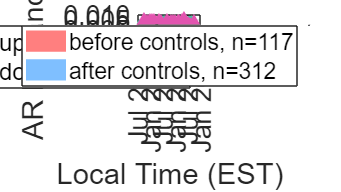


%%line at SDK uncertainties to signify comparison 
xline(0.00126, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)
xline(-0.00126, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)

%%lims
xlim([-0.0209, 0.0259])
xticks(-0.020:0.01:0.020)
ylim([0, 0.8])
% yticks(0:15:60)

%%labels
pbaspect([1.3, 1, 1])
ax.FontSize = 20;
xlabel("AR Enhancement")
ylabel("Normalized Observation Counts")

legend(strcat("before controls, n=", num2str(length(unravelTT(diffCOV(indsBefore & ~indsShutdown, :))))), ...
    strcat("after controls, n=", num2str(length(unravelTT(diffCOV(indsAfter, :))))), ...
    "location", "northeast", "Fontsize", 17)
% legend boxoff

hold off

% %%% export figures
% cd ..\Figures
% a = annotation('rectangle',[0 0 1 1],'Color','w'); %add padding
% fn = "Figure 5 a b.png";
% exportgraphics(fig1, fn)
% delete(a) %make plot interactive again
% 
% fn = "Figure 5 c d.png";
% exportgraphics(fig2, fn)
% delete(a) %make plot interactive again
% 
% fn = "Figure 5 e f.png";
% exportgraphics(fig3, fn)
% delete(a) %make plot interactive again
% 
% cd ..\Data

%% for paper: evaluate stats

%%change in std
%before
stdSTER_AR = std(unravelTT(dataSTER), 0, "all", "omitnan"); %raw AR
stdSSG_AR = std(unravelTT(dataSSG), 0, "all", "omitnan"); %raw AR
stdSTER_enhance = std(unravelTT(diffSTER), 0, "all", "omitnan"); %AR enhancment
stdSSG_enhance = std(unravelTT(diffSSG), 0, "all", "omitnan"); %AR enhancment

%percent differences
stdDiffSTER = (stdSTER_AR - stdSTER_enhance)/stdSTER_AR;
stdDiffSSG= (stdSSG_AR - stdSSG_enhance)/stdSSG_AR;

%%range of enhacements
maxk(unravelTT(diffSTER), 4)

ans =     0.0300
    0.0120
    0.0113
    0.0086


mink(unravelTT(diffSTER), 4)

ans =    -0.0173
   -0.0173
   -0.0166
   -0.0154


maxk(unravelTT(diffSSG), 4)

ans =     0.0279
    0.0275
    0.0204
    0.0173


mink(unravelTT(diffSSG), 4)

ans =    -0.0165
   -0.0152
   -0.0120
   -0.0112


maxk(unravelTT(diffCOV), 4)

ans =     0.0665
    0.0222
    0.0103
    0.0098


mink(unravelTT(diffCOV), 4)

ans =    -0.0174
   -0.0171
   -0.0169
   -0.0137


ans = 0.0015

ans = 0.0016

ans = 0.0014

ans = 0.0020

ans = 0.0013